% Constants
rho = 1000; % Water density (kg/m^3)
g = 9.81; % Gravity (m/s^2)
Pb = 101325; % Atmospheric pressure (Pa)
Kb = 1.45e-10; % Compressibility of water (Pa^-1)
pi = 3.14159;
% User inputs
D = input("Enter the desired depth of operation (m): ");
V = input("Enter the desired cruising speed (m/s): ");
T = input("Enter the desired mission duration (hours): ");
Cd_input = input("Enter the drag coefficient (default = 0.5): ");
Cp_input = input("Enter the prismatic coefficient (default = 0.6): ");
Cs_input = input("Enter the wetted surface area coefficient (default = 0.7): ");
visc = input("Enter the Kinematic viscosity of fluid (m2/s): ")

visc = 1.3000e-06

d_payload = input("Enter the payload diameter (m): ");
l_payload = input("Enter the payload length (m): ");
w_payload = input("Enter the payload weight (kg): ");
w_battery = input("Enter the battery weight (kg): ");
battery_capacity = input("Enter the battery capacity (Wh): ");
d_vehicle = input("Enter the vehicle diameter (m): ");
l_vehicle = input("Enter the vehicle length (m): ");
S_fin=input("Enter the area of fin in (m2): ");
b_fin=input("Enter the span of fin in (m): ");
Sweep=input("Enter the desired sweep in deg:");
AoA=input("Enter the angle of attack in deg:");
t_c=input("Enter the thickness to chord ratio:");

% Define the radius and length of the nose cone
r_max = 0.27;      % maximum radius
L_tail = 0.29;    % length of the tail
semi_angle = 24.5;  % nose cone semi angle in degrees
bluntness = 3.5;    % fraction of cone length for the flat section

% Define the radius and length of the cylinder
r_cyl = 0.165;     % radius of the cylinder
L_cyl = 1.5;      % length of the cylinder

% Define the radius and length of the nose cap
r_cap = 0.165;    % radius of the cap
L_cap = 0.66;      % length of the cap

% Define the number of points to use for the surfaces
n = 50;

% Calculate the nose cone base radius
r_base = r_max / tand(semi_angle);

% Define the angles and heights for the surface of the cone
theta_cone = linspace(0,2*pi,n);
z_cone = linspace(0,L_tail,n);
[theta_cone,z_cone] = meshgrid(theta_cone,z_cone);

% Calculate the radius at each point along the cone height
r_cone = r_base - z_cone * (r_base / L_tail);

% Add a flat section to the tip of the cone
flat_length = L_tail * bluntness;
flat_idx = find(z_cone >= L_tail-flat_length);
r_cone(flat_idx) = r_cone(flat_idx(1)) * (1 - (z_cone(flat_idx) - (L_tail-flat_length)) / flat_length);

% Create the surface of the nose cone
x_cone = r_cone .* cos(theta_cone);
y_cone = r_cone .* sin(theta_cone);
z_cone =  -(z_cone -0.06*L_tail); % shift nose cone downwards

% Define the angles and heights for the surface of the cylinder
theta_cyl = linspace(0,2*pi,n);
z_cyl = linspace(0,L_cyl,n);
[theta_cyl,z_cyl] = meshgrid(theta_cyl,z_cyl);

% Create the surface of the cylinder
x_cyl = r_cyl .* cos(theta_cyl);
y_cyl = r_cyl .* sin(theta_cyl);
z_cyl = z_cyl;

% Define the angles and heights for the surface of the nose cap
theta_cap = linspace(0,2*pi,n);
phi_cap = linspace(0,pi/2,n);
[theta_cap,phi_cap] = meshgrid(theta_cap,phi_cap);

% Create the surface of the nose cap (semi-ellipsoid)
x_cap = r_cap * sin(phi_cap) .* cos(theta_cap);
y_cap = r_cap * sin(phi_cap) .* sin(theta_cap);
z_cap = z_cyl(end) + r_cap * cos(phi_cap);

% Shift the nose cone so that its base aligns with the open base of the cylinder
z_cone = z_cone;

% Define the rotation angles
theta_x = 90; % rotation angle around x-axis in degrees
theta_y = 180; % rotation angle around y-axis in degrees
theta_z = 0; % rotation angle around z-axis in degrees

% Convert the angles to radians
theta_x = theta_x * pi / 180;
theta_y = theta_y * pi / 180;
theta_z = theta_z * pi / 180;

% Define the rotation matrices
Rx = [1, 0, 0; 0, cos(theta_x), -sin(theta_x); 0, sin(theta_x), cos(theta_x)];
Ry = [cos(theta_y), 0, sin(theta_y); 0, 1, 0; -sin(theta_y), 0, cos(theta_y)];
Rz = [cos(theta_z), -sin(theta_z), 0; sin(theta_z), cos(theta_z), 0; 0, 0, 1.5];

% Calculate the composite rotation matrix
R = Rx * Ry * Rz;

% Apply the rotation to the coordinates of each surface
x_cone_rot = zeros(size(x_cone));
y_cone_rot = zeros(size(y_cone));
z_cone_rot = zeros(size(z_cone));

x_cyl_rot = zeros(size(x_cyl));
y_cyl_rot = zeros(size(y_cyl));
z_cyl_rot = zeros(size(z_cyl));

x_cap_rot = zeros(size(x_cap));
y_cap_rot = zeros(size(y_cap));
z_cap_rot = zeros(size(z_cap));

for i = 1:numel(x_cone)
v = [x_cone(i), y_cone(i), z_cone(i)]';
v_rot = R * v;
x_cone_rot(i) = v_rot(1);
y_cone_rot(i) = v_rot(2);
z_cone_rot(i) = v_rot(3);
end

for i = 1:numel(x_cyl)
v = [x_cyl(i), y_cyl(i), z_cyl(i)]';
v_rot = R * v;
x_cyl_rot(i) = v_rot(1);
y_cyl_rot(i) = v_rot(2);
z_cyl_rot(i) = v_rot(3);
end

for i = 1:numel(x_cap)
v = [x_cap(i), y_cap(i), z_cap(i)]';
v_rot = R * v;
x_cap_rot(i) = v_rot(1);
y_cap_rot(i) = v_rot(2);
z_cap_rot(i) = v_rot(3);
end

% Calculate the volume of the nose cone
V_cone = Cp_input * pi/3 * L_tail * (r_base^2 + r_base*r_max + r_max^2);
disp(['Volume of nose cone: ', num2str(V_cone), ' m^3']);

Volume of nose cone: 0.11525 m^3



% Calculate the volume of the cylinder
V_cyl = Cp_input*pi * r_cyl^2 * L_cyl;
disp(['Volume of cylinder: ', num2str(V_cyl), ' m^3']);

Volume of cylinder: 0.083392 m^3



% Calculate the volume of the nose cap
V_cap = Cp_input * 4/3 * pi * r_cap^3;
disp(['Volume of nose cap: ', num2str(V_cap), ' m^3']);

Volume of nose cap: 0.012231 m^3



% Calculate the total volume of the AUV
V_AUV = V_cone + V_cyl + V_cap;
disp(['Total volume of AUV: ', num2str(V_AUV), ' m^3']);

Total volume of AUV: 0.21088 m^3



% Calculate the area of the hull
r_vehicle = sqrt(V_AUV / (pi * l_vehicle));
CSA = pi * r_vehicle^2;
fprintf('Hull area: %f m^2\n', CSA);

Hull area: 0.084351 m^2


% Calculate the centroid of the hull
centroid = l_vehicle/2;
fprintf('Centroid of the hull: %f m\n', centroid);

Centroid of the hull: 1.250000 m



% Calculations
A = pi * ((d_vehicle)^2) / 4; % Cross-sectional area of the AUV
S = Cs_input*pi*d_vehicle*l_vehicle; % Wetted Surface area of AUV
Fb = rho * g * V_AUV ; % Buoyancy force
Vt = V / (1 - Fb / (rho * g * A)); % Terminal velocity
Re = V_AUV * l_vehicle / visc; % Reynolds number
Cf = 0.075/((log(Re)-2)^2); %Frictional Coefficient
Cd = Cf*(1+1.5*((d_vehicle/l_vehicle)^1.5+7*(d_vehicle/l_vehicle)^3)); % Effective drag coefficient
Df = 0.5 * Cd_input * rho * V_AUV^2 * A; % Drag force
Thrust_power = 0.5*rho*V_AUV^3*S*Cd_input; % Thrust_power
P = Df * V_AUV; % Power required
E = P * T * 3600; % Energy required (J)
Fr = V/sqrt(g*l_vehicle); % Froude number

% Calculate the underwater volume of the hull
underwater_volume = V_AUV- (CSA * centroid);
fprintf('Underwater volume of the hull: %f m^3\n', underwater_volume);

Underwater volume of the hull: 0.105439 m^3



% Calculate the center of buoyancy
center_of_buoyancy = centroid + (underwater_volume / (CSA * rho));
fprintf('Center of buoyancy: %f m\n', center_of_buoyancy);

Center of buoyancy: 1.251250 m



% Total mass of AUV
M_total = w_payload + w_battery + (rho * underwater_volume);


% Weight of AUV
W_g = M_total*g; 

% Apparent weight of AUV
F_apparent = W_g-Fb;

% Battery life calculation
V_bat = 12; % Battery voltage (V)
I = P / V_bat; % Current drawn by the AUV (A)
t_life = battery_capacity / (V_bat * I); % Battery life (hours)
Power_from_battery = V_bat*I;

% Outputs
fprintf("AUV size calculation results:\n");

AUV size calculation results:


fprintf("Terminal velocity = %.2f m/s\n", Vt);

Terminal velocity = -1.72 m/s


fprintf("Effective drag coefficient = %.3f\n", Cd); 

Effective drag coefficient = 0.001


fprintf("Buoyancy Force = %.3f N\n", Fb); 

Buoyancy Force = 2068.704 N


fprintf("Apparent Weight = %.3f N\n", F_apparent); 

Apparent Weight = -1014.732 N


fprintf("Drag force = %.2f N\n", Df);

Drag force = 0.64 N


fprintf("Thrust power = %.2f J/s\n", Thrust_power);

Thrust power = 2.90 J/s


fprintf("Power required = %.2f W\n", P);

Power required = 0.14 W


fprintf("Energy required = %.2f J\n", E);

Energy required = 487.20 J


fprintf("Ideal Power from Battery = %.2f J\n", Power_from_battery);

Ideal Power from Battery = 0.14 J


fprintf("Battery life = %.2f hours\n", t_life);

Battery life = 427.09 hours


fprintf("Reynolds number = %.2f \n", Re);

Reynolds number = 405532.90 


fprintf("Surface Area = %.2f m^2\n", S);

Surface Area = 2.06 m^2


fprintf("Froude Number = %.2f \n", Fr);

Froude Number = 0.41 


fprintf("Total mass of AUV = %.2f kg\n", M_total);

Total mass of AUV = 107.44 kg


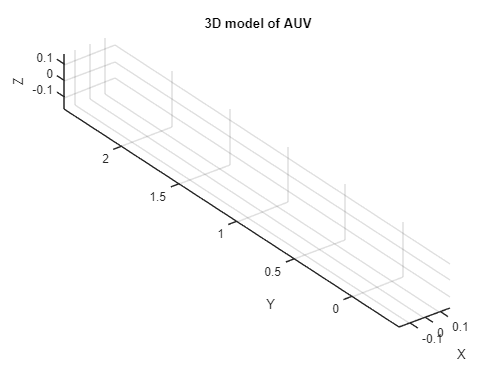


% Plot the AUV
figure(2)
surf(x_cone_rot, y_cone_rot, z_cone_rot)
hold on
surf(x_cyl_rot, y_cyl_rot, z_cyl_rot)
surf(x_cap_rot, y_cap_rot, z_cap_rot)
axis equal
xlabel('X')
ylabel('Y')
zlabel('Z')
title('3D model of AUV')


%Calculate the Aspect ratio of the fin
AR=(b_fin^2)/S_fin;
fprintf('AR of fin: %f \n', AR);

AR of fin: 1.474876 



%Calculate the Average chord of fin
c_avg=sqrt(S_fin/AR);
fprintf('Average chord of fin: %f m\n', c_avg);

Average chord of fin: 0.522078 m



%Calculate the average span of fin
b_avg=c_avg/AR;
fprintf('Average span of fin: %f m\n', b_avg);

Average span of fin: 0.353981 m



%Calculate the area of fin from averages
S_avg=b_avg*c_avg;
fprintf('Average area of fin: %f m^2\n', b_avg);

Average area of fin: 0.353981 m^2



%Calculate the non dimensionalised area
S_nd=S_fin/l_vehicle^2;
fprintf('Non dimensionalised area of fin: %f \n', b_avg);

Non dimensionalised area of fin: 0.353981 



%Calculate lift slope for fin
Sweep = Sweep * pi/180;
a = (1.8*pi*2*AR)/((sqrt(4*AR^2)/(cos(Sweep)^4+4))*(cos(Sweep)+1.8));
fprintf('Slope of lift curve: %f \n', a);

Slope of lift curve: 10.032442 rad



AoA = AoA * pi / 180;
fprintf('Angle of Attack in radians %f \n', AoA);

Angle of Attack in radians 0.104720 



%Calculate the lift coefficient 
c_l=a*AoA; 
fprintf('Lift coefficient %f \n', c_l);

Lift coefficient 1.050594 



%Calculate the drag coefficient variable dependent on Re
c_f=0.075/((log(Re)-2)^2);
fprintf('section drag coefficient %f \n', c_f);

section drag coefficient 0.000630 



%Calculate the induced drag coefficient
c_di=(c_l^2)/pi*2*AR;
fprintf('Coefficient of Induced drag %f \n', c_di);

Coefficient of Induced drag 1.036348 



%Calculate the parasite drag coefficient
c_do=c_f*(1+2*t_c+60*(t_c)^4);
fprintf('Coefficient of Parasite drag %f \n', c_do);

Coefficient of Parasite drag 0.000645 



%Calculate the drag coefficient
c_d = c_do+c_di;
fprintf('Total drag coefficient from fin %f \n', c_d);

Total drag coefficient from fin 1.036993 



% Calculate the x-location of the center of pressure
x_cop = l_vehicle/4 + d_vehicle/2 * (0.287 + 1.554*(d_vehicle/l_vehicle) - 0.457*(d_vehicle/l_vehicle)^2 + 0.104*(d_vehicle/l_vehicle)^3);
fprintf('The center of pressure for a Myring hull with diameter %0.2f meters and length %0.2f meters is located %0.2f meters from the bow.\n', d_vehicle, l_vehicle, x_cop);



disp(upper('ALL VALUES HAVE BEEN ESTIMATED FOR THE PRELIMINARY DESIGN'));

ALL VALUES HAVE BEEN ESTIMATED FOR THE PRELIMINARY DESIGN \N
